# Week 7 Lecture 2: Numerical Integration

In this lecture, we will discuss several methods for numerical integration.  The general setup will be exactly the same as for differentiation.  We will either be given a function $f(x)$ and asked to compute 

$\int_{a}^{b}f(x)\,\textrm{d}x,$              (1)

or we will be given a set of points $(x_0, y_0)$, $(x_1, y_1)$, ..., $(x_N, y_N)$, where $y_k = f(x_k)$ for some (usually unkown) function $f(x)$ and then asked to compute 


$$\int_{a}^{b}f(x)\,\textrm{d}x.$$


By convention, we will always assume that $a = x_0 < x_1 < \cdots < x_N = b$ and that the points are all evenly spaced, so $x_k - x_{k-1} = \Delta x$ is the same for all $k$.  That is, we will assume that $x_k = a + k\Delta x$ for all $0\leq k \leq N$.  The assumption that the points are in order is really no restriction at all, since we can always re-organize any data we are given.  The assumption that these points are evenly spaced is more restrictive.  In practice, it is very common to have evenly spaced data (perhaps because you are making measurements at regular times or at locations on a regular grid), but it is not strictly necessary.  It turns out that none of the methods we will discuss actually require this even spacing, but the formulas become much messier when $\Delta x$ is not constant.  It is also worth noting that there are $N+1$ points here, not just $N$, because we start counting at $x_0$.  

As in the previous two lectures, it is easy to switch back and forth between these two settings.  If we are given a function $f(x)$, then we can simply plug in all of our $x$-values and then forget about the function.  If we are given a set of $(x_k, y_k)$ points, then we can (at least on paper) pretend that $y_k = f(x_k)$ and just never use a formula for $f(x)$.  When working on paper, it is generally much more convenient to think in terms of a function $f$, but in real world applications we often only have a set of data points, so it is important to be comfortable with both sets of notation.  

Remember that the integral in (1) can be thought of as the area under the curve $f(x)$ between $x = a$ and $x = b$.  All of our methods will be based upon the following idea: We can chop this area up into many smaller regions, then calculate the area of each smaller region and add them all up.  As long as the smaller regions approximately cover the whole area, then we will get a good approximation to the total integral.  

It turns out that integration methods are generally much more difficult to analyze than difference schemes, so we will only fully analyze the simplest methods.  You have almost certainly seen these simple methods in a basic calculus class.  

### Left Hand Rule

The basic idea in our first approach is to chop the area under the curve $f(x)$ into $N$ different rectangles.  The base of the first rectangle will be the interval $[x_0, x_1]$, then the base of the second rectangle will be $[x_1, x_2]$, and so on, all the way to the $N$th rectangle, whose base will be $[x_{N-1}, x_N]$.  In general, the base of the $k$th rectangle will be the interval $[x_{k-1}, x_k]$.  Because we assumed that the $x$-values were all evenly spaced, the width of each of these intervals is just $\Delta x$.  We will determine the height by evaluating the function $f(x)$ at some point in the base.  The only real choice involved here is which point we use to determine the height.  

The first approximation method we will discuss is called the *left hand rule* or *left rectangle rule*.  In this method, we choose the height of the $k$th rectangle to be $f(x_{k-1})$.  (The name comes from the fact that $x_{k-1}$ is the leftmost point in the base of the rectangle.)  

We can visualize this with the function `plot_lhr`, which is included at the bottom of the script.  For example, here are the rectangles for the function $f(x) = \sin(x) + 3$ with $a = 0$, $b = 10$ and $\Delta x = 2$: 

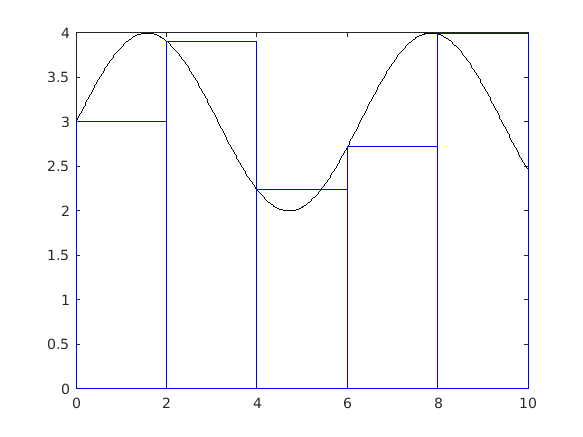

f = @(x)(sin(x) + 3);
a = 0; 
b = 10; 
dx = 2;
plot_lhr(f, a, b, dx)

If we plot the same function with a smaller $\Delta x$, we get 

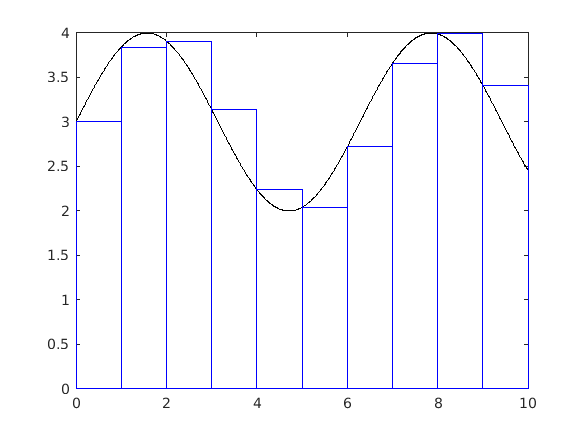

dx = 1;
plot_lhr(f, a, b, dx)

If we shrink $\Delta x$ even further, we get 

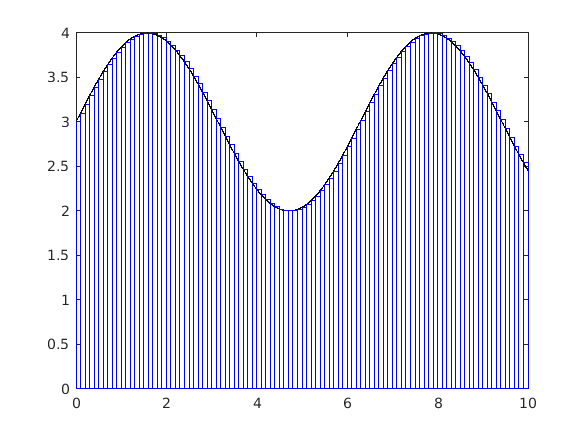

dx = 0.1;
plot_lhr(f, a, b, dx)

The area of the $k$th rectangle is just the width times the height, or $\Delta xf(x_{k-1})$.  To find the area under the whole curve, we just add up the area of all $N$ rectangles, so we get 


$$\int_{a}^{b}f(x)\,\textrm{d}x \approx \Delta x f(x_0) + \Delta x f(x_1) + \cdots + \Delta x f(x_{N-1}) = \sum_{k=0}^{N-1}\Delta x f(x_k) = \Delta x\sum_{k=0}^{N-1}f(x_k).$$


How good an approximation is this?  More importantly, how does the quality of this approximation change as we reduce $\Delta x$?  To answer that question, we will first look at a simpler problem and only try to find the integral over one of the rectangles (i.e., the integral from $x_{k-1}$ to $x_{k}$).  The left hand rule approximation to this integral is 


$$\int_{x_{k-1}}^{x_k}f(x)\,\textrm{d}x \approx \Delta x f(x_{k-1}).$$


We can also approximate this integral by using a Taylor expansion of $f$.  In particular, we will expand $f(x)$ about the point $x_{k-1}$.  We get 


$$\int_{x_{k-1}}^{x_k}f(x)\,\textrm{d}x = \int_{x_{k-1}}^{x_k}f(x_{k-1}) + (x - x_{k-1})f'(x_{k-1}) + \frac{(x - x_{k-1})^2}{2}f''(x_{k-1}) + \mathcal{O}((x - x_{k-1})^3)\,\textrm{d}x.$$


This integral looks quite complicated, but we are only integrating with respect to $x$, not $x_{k-1}$, so it is really just a polynomial.  We therefore get 


$$\int_{x_{k-1}}^{x_k}f(x)\,\textrm{d}x = \left[xf(x_{k-1}) + \frac{(x - x_{k-1})^2}{2}f'(x_{k-1}) + \frac{(x - x_{k-1})^3}{6}f''(x_{k-1}) + \mathcal{O}((x - x_{k-1})^4)\right]_{x = x_{k-1}}^{x_k}$$


If we plug in the endpoints $x = x_{k-1}$ and $x = x_{k}$ into this antiderivative, then many of the terms become zero and we are left with 


$$\int_{x_{k-1}}^{x_k}f(x)\,\textrm{d}x = (x_k - x_{k-1})f(x_{k-1}) + \frac{(x_k - x_{k-1})^2}{2}f'(x_{k-1}) + \frac{(x_{k} - x_{k-1})^3}{6}f''(x_{k-1}) + \mathcal{O}((x_k - x_{k-1})^4)$$



$$= \Delta xf(x_{k-1}) + \frac{(\Delta x)^2}{2}f'(x_{k-1}) + \frac{(\Delta x)^3}{6}f''(x_{k-1}) + \mathcal{O}(\Delta x^4)$$


Since $\Delta x$ is supposed to be very small, higher powers of $\Delta x$ will be even smaller, so we can safely ignore the $\mathcal{O}(\Delta x^3)$ terms.  This means that we have 


$$\int_{x_{k-1}}^{x_k}f(x)\,\textrm{d}x \approx \Delta x f(x_{k-1}) + \frac{(\Delta x)^2}{2}f'(x_{k-1}).$$


Notice that the first term matches our approximation from the left hand rule.  This means that the left hand rule gives us a good approximation of the integral over this small interval and that the error from the left hand rule is $\frac{(\Delta x)^2}{2}f'(x_{k-1})$.  In particular, this error has a $\Delta x^2$ in it, so we say that it is second order.  We call this quantity the *local error* for the left hand rule, and we say that the left hand rule has second order local error.  

However, it is important to remember that this isn't really the problem we wanted to solve.  We just found a second order approximation to the integral of $f(x)$ from $x_{k-1}$ to $x_k$, but we wanted to approximate the integral from $a$ to $b$.  The total integral involves $N$ of these small intervals, so the total error will be roughly $N\frac{(\Delta x)^2}{2}f'(x_{k-1})$.  You might be tempted to think that $N$ is simply a constant, so we can ignore it when we use big-oh notation and just say that the total error is $\mathcal{O}(\Delta x^2)$, but this would be incorrect.  The problem is that $N$ actually depends on $\Delta x$.  If we make $\Delta x$ smaller, then we need more rectangles to cover the whole area.  In particular, we have $N = (b - a)/\Delta x$.  This means that the error for the entire integral is $\frac{(b - a)\Delta x}{2}f'(x_{k-1})$, which only has a $\Delta x^1$.  We call this quantity the *global error* of the left hand rule and we say that the left hand rule has first order global error.  

It is very easy to implement the left hand rule in MATLAB.  As an example, let's try to find the integral of $f(x) = \sin(x) + 3$ between $a = 0$ and $b = 10$.  The antiderivative of this function is $F(x) = -\cos(x) + 3x$, and so the actual solution is 

$\int_{a}^{b}\sin(x) + 3\,\textrm{d}x = \left(-\cos(b) + 3b\right) - \left(-\cos(a) + 3a\right)$.

a = 0; 
b = 10; 

true_solution = (-cos(b) + 3*b) - (-cos(a) + 3*a)

true_solution =   31.839071529076453


To set up our problem, we need to choose a list of $x$-values and calculate the corresponding $y$-values.  For example, if we choose $\Delta x = 1$ then we have 

dx = 1;
x = a:dx:b;
y = sin(x) + 3;

To calculate the left hand rule, we have to add up $\left(\Delta x\right)y_k$ for every $y$-value except for the last one.  One approach (which we have used several times in this class already) is to add these terms one at a time in a loop. For example,

LHR = 0;
for k = 1:length(x)-1
    LHR = LHR + dx * y(k);
end
LHR

LHR =   31.955209482107382


Another option is to collect all of the necessary 𝑦 values and then use the built-in function `sum` to add them all up. Since we want to add the first through the second to last entries of 𝑦, we can use

LHR = dx * sum(y(1:end-1))

LHR =   31.955209482107382


### Right Hand Rule

There was no particular reason to choose the left endpoint of each interval in the previous approximation.  We could just as easily have chosen the right endpoint (or any point in between, for that matter, but we will stick to the endpoints for now).  

Here are some illustrations of the right hand rule for different choices of $\Delta x$: 

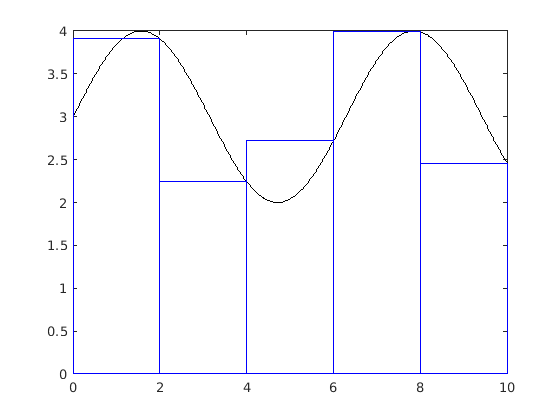

f = @(x)(sin(x) + 3);
a = 0; 
b = 10; 
dx = 2;
plot_rhr(f, a, b, dx)

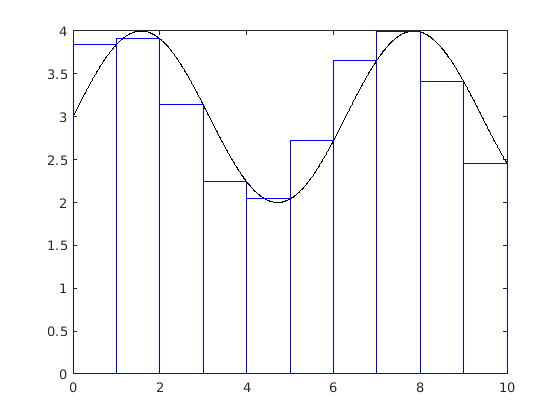

dx = 1;
plot_rhr(f, a, b, dx)

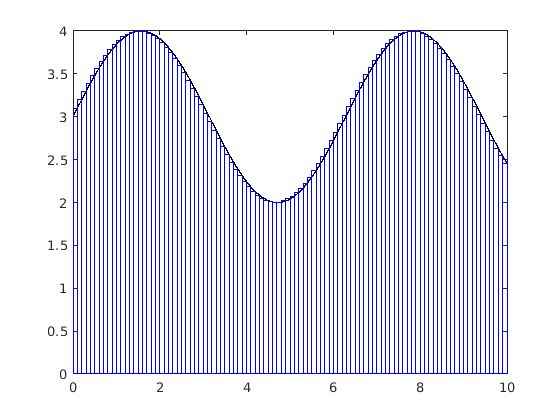

dx = 0.1;
plot_rhr(f, a, b, dx)

The area of the $k$th rectangle is now $\Delta xf(x_k)$, and so we have the approximation 


$$\int_{a}^{b}f(x)\,\textrm{d}x \approx \Delta xf(x_1) + \Delta xf(x_2) + \cdots + \Delta xf(x_N) = \sum_{k=1}^{N}f(x_k)\Delta x = \Delta x\sum_{k=1}^{N}f(x_k).$$


We call this method the *right hand rule* or *right rectangle rule*.  Notice that the formula is almost exactly the same as for the left hand rule, but the sum starts at 1 instead of 0 and goes up to $N$ instead of $N - 1$.  That is, we use every $f(x_k)$ value except for $f(x_0)$, whereas in the left hand rule we used every value except for $f(x_N)$.  

We can calculate the error in exactly the same way as we did for the left hand rule (except that we would need to Taylor expand about $x_{k}$ instead of about $x_{k-1}$).  If we do so, we will find that the local error is approximately $-\frac{(\Delta x)^2}{2}f'(x_{k})$, and so the right hand rule has second order local error.  Likewise, we would find that the global error is approximately $-\frac{(b - a)\Delta x}{2}f'(x_k)$, and so the right hand rule has first order global error.  

Like the left hand rule, it is easy to implement this method in MATLAB.  Let's try the same integral as above: 

a = 0; 
b = 10; 

true_solution = (-cos(b) + 3*b) - (-cos(a) + 3*a)

true_solution =   31.839071529076453


dx = 1;
x = a:dx:b;
y = sin(x) + 3;

To calculate the right hand rule, we have to add up $\left(\Delta x\right)y_k$ for every $y$-value except for the first one.  As before, we can either do this with a loop or the built-in sum function.  

RHR = 0;
for k = 2:length(x)
    RHR = RHR + dx * y(k);
end
RHR

RHR =   31.411188371218010


RHR = dx * sum(y(2:end))

RHR =   31.411188371218010


### Trapezoidal Rule

It is worth noting that the leading error terms for the left and right hand rules look very similar, but with opposite signs.  This suggests an improvement very similar to our approach with the central difference scheme.  We can calculate both the right and left hand approximations and then average the two.  We would then obtain the formula


$$\int_{a}^{b}f(x)\,\textrm{d}x \approx \frac{1}{2}\left[\sum_{k=0}^{N-1}\Delta xf(x_k) + \sum_{k=1}^{N}f(x_k)\Delta x\right].$$


We can actually simplify this even more by noting that most of the terms appear twice, once in each sum.  The only two exceptions are the $k = 0$ and $k = N$ terms, which only appear once.  We can therefore rewrite this approximation as 


$$\int_{a}^{b}f(x)\,\textrm{d}x \approx \frac{\Delta x}{2}\left[f(x_0) + 2\sum_{k=1}^{N-1}f(x_k) + f(x_N)\right].$$


This approximation is called the *trapezoidal rule*.  The name comes from the fact that we can also derive this method by dividing the total area up into many small trapezoids instead of rectangles.  For example: 

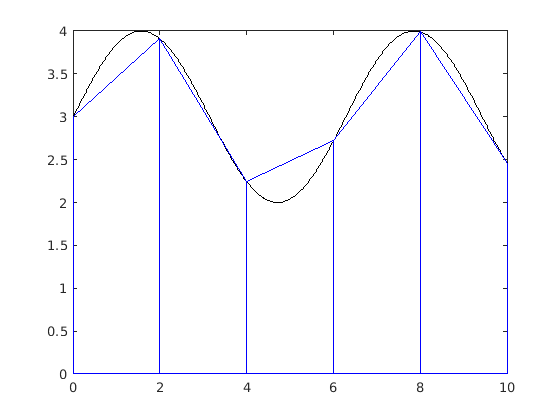

f = @(x)(sin(x) + 3);
a = 0; 
b = 10; 
dx = 2;
plot_trap(f, a, b, dx)

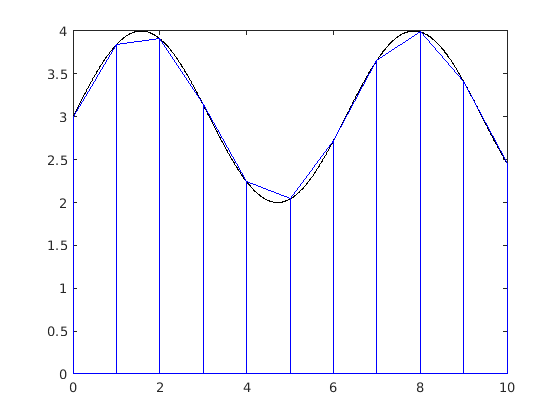

dx = 1;
plot_trap(f, a, b, dx)

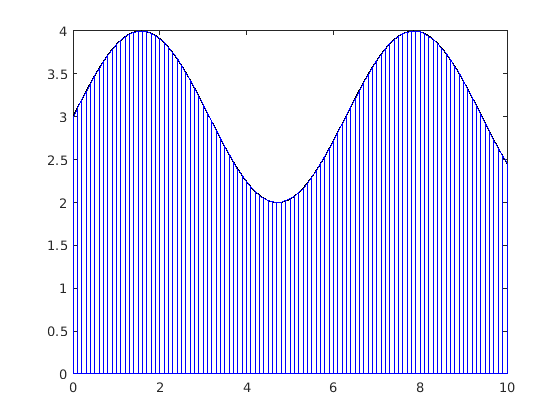

dx = 0.1;
plot_trap(f, a, b, dx)

The analysis for this method is slightly more complicated than before, but it turns out that the trapezoidal rule has third order local error and second order global error.  

As an example, let's use the trapezoidal method to approximate the same integral as before: 

true_solution = (-cos(b) + 3*b) - (-cos(a) + 3*a)

true_solution =   31.839071529076453


dx = 1;
x = a:dx:b;
y = sin(x) + 3;

We can either find the left and right hand rules first and then average them

LHR = dx * sum(y(1:end-1));
RHR = dx * sum(y(2:end));

trap = (LHR + RHR) / 2

trap =   31.683198926662698


or we can use the formula directly

trap = (dx/2) * (y(1) + 2*sum(y(2:end-1)) + y(end))

trap =   31.683198926662694


### Builtin Functions

MATLAB has several useful builtin functions for approximating integrals.  First, there is the `trapz` command, which implements the trapezoidal rule.  The easiest way to use this command is to give it a vector of $x$-values and a vector of $y$-values corresponding to the $(x_k, y_k)$ points from our data set.  For example, if we were solving the same problem as above

f = @(x)(sin(x) + 3);
a = 0; 
b = 10; 

true_solution = (-cos(b) + 3*b) - (-cos(a) + 3*a)

true_solution = 31.8391

dx = 1;
x = a:dx:b;
y = f(x);

then we could just write 

trap = trapz(x, y)

trap = 31.6832

It is important to keep in mind that `x` and `y` are vectors, not functions.  MATLAB figures out the spacing $\Delta x$ by looking at the vector `x`.  

Another important builtin function is called `quad`.  This function implements Simpson's rule, which puts a parabola at the top of each of the small rectangles from the left and right hand rules.  The syntax for this function is 

Int = quad(f, a, b)

Int = 31.8391

Notice that `quad` takes a function `f`, not a vector of `y` values.  You also do not specify $\Delta x$ for quad.  Instead, it tries to choose $\Delta x$ so that the error is around $10^{-6}$.  

For the most part, `quad` works perfectly fine, but it is being phased out in MATLAB (which means that it might not work in future versions).  You will still see `quad` used in older code, as well as in the video lectures for this class, but it is no longer a good idea to rely on it in your own code.  Instead, you should use the `integral` command.  The syntax for `integral` is the same as for `quad`: 

Int = integral(f, a, b)

Int = 31.8391

The difference is that `integral` uses substantially more sophisticated algorithms than we have covered here.  As with `quad`, the `integral` command chooses its own interval widths in order to make the error around $10^{-6}$.  You should always use `integral()` in this class instead of `quad`.  Unfortunately, the python version of `integral()` is called `quad()`, and so the instructions on the homework will say something like "use integral or quad to solve this problem".  If you are using MATLAB, you need to use `integral`.  

#### Local functions

function plot_lhr(f, a, b, dx)
    xplot = a:(dx/100):b;
    x = a:dx:b;
    n = length(x);
    y = f(x);
    
    plot(xplot, f(xplot), 'k')
    hold on
    
    for k = 1:n-1
        x_rect = [x(k) x(k) x(k+1) x(k+1) x(k)];
        y_rect = [0 f(x(k)) f(x(k)) 0 0];
        plot(x_rect, y_rect, 'b')
    end
    hold off
end

function plot_rhr(f, a, b, dx)
    xplot = a:(dx/100):b;
    x = a:dx:b;
    n = length(x);
    y = f(x);
    
    plot(xplot, f(xplot), 'k')
    hold on
    
    for k = 1:n-1
        x_rect = [x(k) x(k) x(k+1) x(k+1) x(k)];
        y_rect = [0 f(x(k+1)) f(x(k+1)) 0 0];
        plot(x_rect, y_rect, 'b')
    end
    hold off
end

function plot_trap(f, a, b, dx)
    xplot = a:(dx/100):b;
    x = a:dx:b;
    n = length(x);
    y = f(x);
    
    plot(xplot, f(xplot), 'k')
    hold on
    
    for k = 1:n-1
        x_rect = [x(k) x(k) x(k+1) x(k+1) x(k)];
        y_rect = [0 f(x(k)) f(x(k+1)) 0 0];
        plot(x_rect, y_rect, 'b')
    end
    hold off
end